# Modelo 1

## Modelo 1

Modelo de crecimiento lineal.

Supongamos que hacemos una imposición mensual de una cantidad en un banco.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=k\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$



$$\begin{array}{l}
k\;\;\;\;\;\;\;\;=\textrm{cantidad}\;\textrm{depositada}\;\textrm{mensualmente}\\
M\left(t\right)=\textrm{cantidad}\;\textrm{de}\;\textrm{dinero}\;\textrm{en}\;\textrm{la}\;\textrm{cuenta}\;\textrm{en}\;\textrm{un}\;\textrm{instante}\;t
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) k M0 t0

edo = diff(M, t, 1) == k;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond);
M(t) = collect(M(t), k)     % para sacar factor comun

$$M(t) = \left(t-t_{0}\right)\,k+M_{0}$$

#### 2. Sustitución de valores iniciales y constante k

k_values =  [2, 3, -2];
ic_values = [0 1; 0 8; 0 1];
t_values = 0:5:10;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso

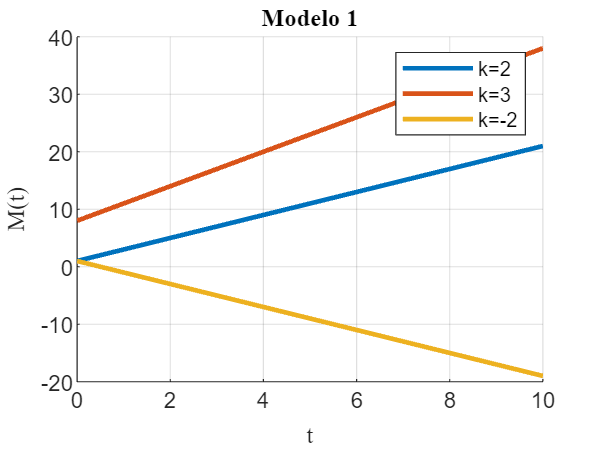

figure;
hold on;

for i = 1:n
    M_subs = subs(M, k, k_values(i));
    M_subs = subs(M_subs, [t0, M0], [ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 1','FontName','latex');
legend('show');
grid on;
hold off;

Estamos ante un modelo de crecimiento lineal. Para:

$k>0\;$crecimiento

$k<0\;$decrecimiento

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$0=k\;$$


La estabilidad no se alcanza para ningún valor de k distinto de 0 ni para ninguna condición inicial, ya que es un modelo lineal, que crece o decrece de manera constante.

No es muy realista porque supone que solo hacemos imposiciones.